# Part 2: Plant image segmentation 

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

In this section, we will import, manipulate, and segment an image of flowers using MATLAB® and gain some intuition on how images are stored and utilized in MATLAB. 

## Import your image

As we have explored in other modules, for most tasks we undertake in MATLAB, there are a couple of different ways we can approach them. Let's use two different methods to import this image.

### Method 1: Use the Import Data Tool 

First, let's try using the** Import Data Tool**. Under the **Home** tab, click 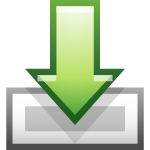 **Import Data**. Click the images folder, then select the image called "flowers.jpg" and select **Open**.

An Import Wizard window will open up and show you information about the variable you are importing, including size. Select **Finish**. 

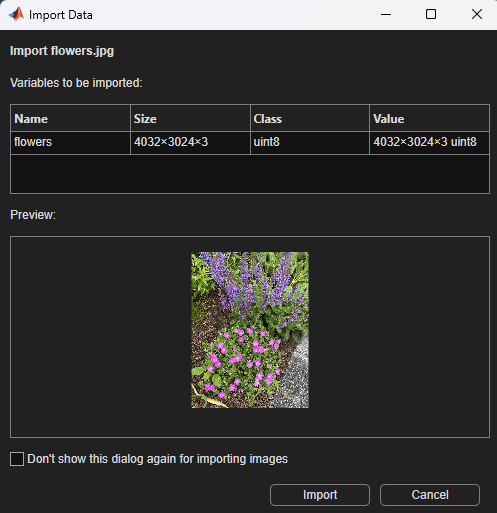

Now the variable `flowers` will be in your workspace! 

### Method 2: Use `imread()`

If you want to do this yourself, simply use the [`imread()`](https://www.mathworks.com/help/matlab/ref/imread.html) function, which reads the image and saves it to the variable you set it to, in this case, `flowers`. First, we have to let MATLAB know where the image is stored (images folder) and add that folder to our path so we can access the image. 

addpath("images")
flowers = imread("flowers.jpg");

## Display your image

Let's explore this image a little bit. 

  We can use [`imshow()`](https://www.mathworks.com/help/images/ref/imshow.html) to display the image. Type` imshow(flowers) `into the code block: 

`imshow() `is the standard way to display images that is provided by the Image Processing Toolbox™. This toolbox also provides [`imageViewer()`](https://www.mathworks.com/help/releases/R2023b/images/ref/imageviewer-app.html), which also displays the image, but provides some additional functionality. For example, we can adjust contrast and explore individual pixels using `imtool`. 

  Type` imageViewer(flowers)` into the box below: 

It is worth pausing and discussing how images are stored in MATLAB. Looking at the value of flowers in the workspace, we can see that it is size  4032x3024x3, so we have 3 dimensions here. Images are stored as numerical arrays, with the number of rows (4032) representing the height of the image and the number of columns (3024) representing the width. Each element in the array represents a single pixel, and the value of that element corresponds to the intensity of the pixel. The third dimension here makes this a 3-D array. This dimension comes from the fact that this image is a color image- so intensity values for each pixel are stored in 3 planes, with each plane representing one color (red, green, and blue, respectively). The combination of the color intensities of each pixel in the red, blue, and green channels makes the unique color of that pixel that your eye perceives. All the pixels together compose the image that you see!

  In the `imageViewer` window, you can toggle seeing Image Metadata as well as an Image Overview in the tool strip. As you zoom and pan through the image, the Image Overview shows your current view with respect to the whole image.  

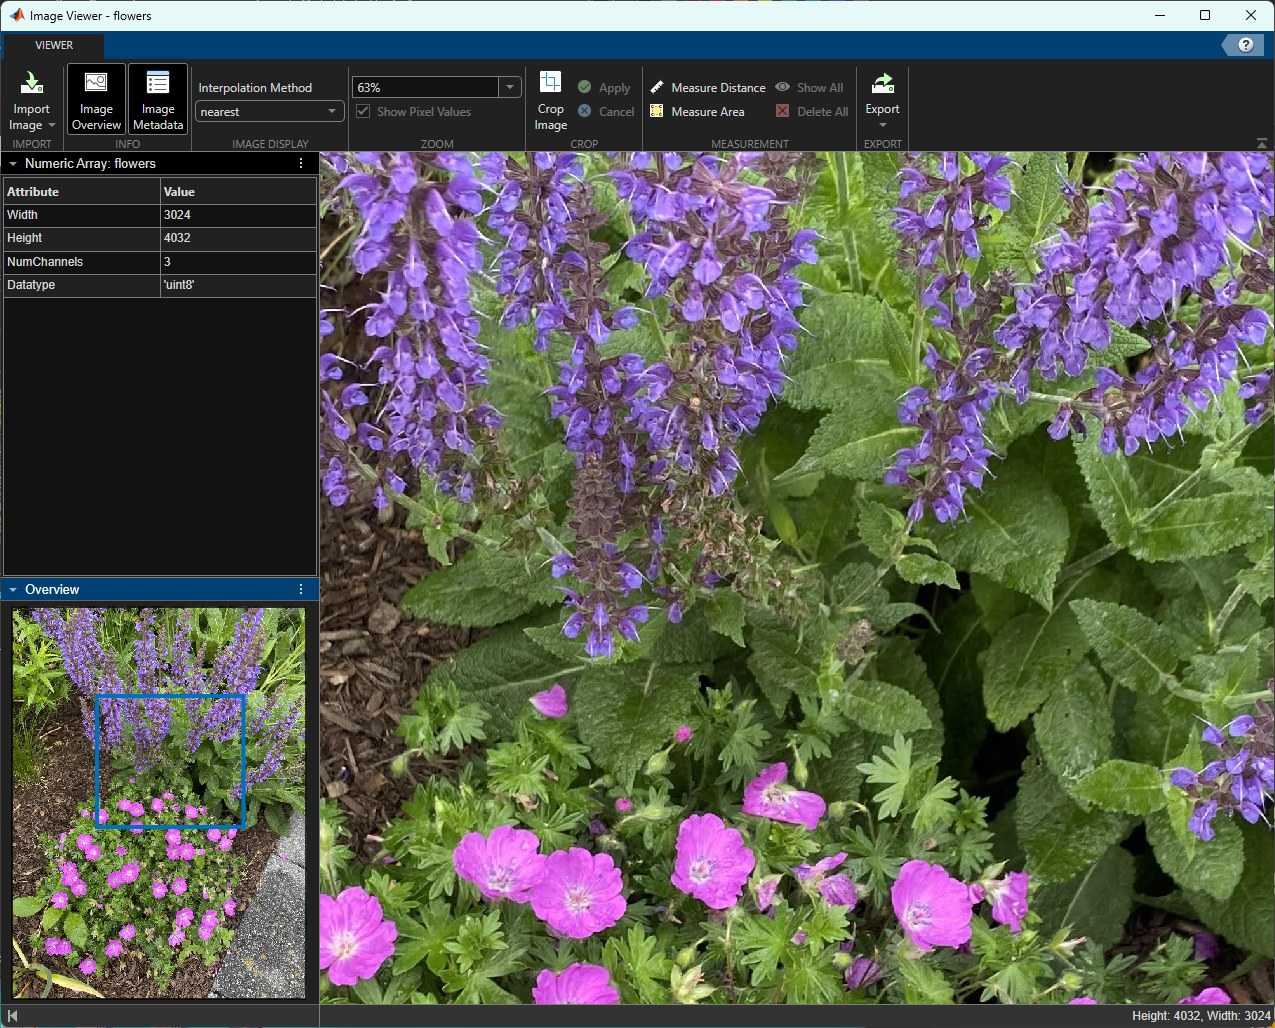

When you're done playing around with the pixel regions, you can close the `imageViewer` window. 

## Manipulate your image

### Extract color planes from color images

You use [indexing](https://www.mathworks.com/help/matlab/math/array-indexing.html) to extract color planes if you want. You will find a more detailed explanation of indexing in the biosciences data module***(add link to module 1 on File Exchange)***. You can also check out the Arrays.mlx script in the [Fundamentals of Programming](https://www.mathworks.com/matlabcentral/fileexchange/103225-fundamentals-of-programming) curriculum module to learn more about how [R, G, B] images are stored and manipulated. 

For example, if we want to look at the red plane of the image, we know we will have to look at all pixels, but only in the red channel. This means we will need all rows and all columns, but only the first plane. To extract this, run: 

redchan = flowers(:,:,1); 
imshow(redchan)

By default, MATLAB represents each channel as a grayscale image once it is extracted. In, this grayscale image, each pixel value represents the intensity of red in that pixel.  Pixel values range from 0 (black/least intense) to 255 (white, most intense). The brightest parts of this image are therefore the most 'red' in the original image. 

Notice that the pink flowers show up "brightest" when we look at the red channel. This is because they have a lot of red in them! 

  Go back to the code block above and change the 3rd input to look at different color planes. Plane 1 is red, plane 2 is green, and plane 3 is blue.

We can split our image into all of its component color channels at once using [`imsplit()`](https://www.mathworks.com/help/images/ref/imsplit.html). Note that we are specifying three outputs to this function (R, G, and B), and each will correspond to one color plane. 

[R,G,B] = imsplit(flowers); 

To view all of these planes at once, we can use the MATLAB function  [`tiledlayout()`](https://www.mathworks.com/help/matlab/ref/tiledlayout.html)**.** The instruction `tiledlayout(2,2)` breaks the figure up into a 2x2 grid (2 rows, 2 columns) and `nexttile` moves to the next available axis. We should add a title on each subplot so we know which channel it is we are looking at! 

t = tiledlayout(2,2);
title(t,"Color Channels for flowers")
nexttile
imshow(R)
title("Red Channel")

Let's put the green channel in position 2: 

nexttile
imshow(G)
title("Green Channel")

And the blue channel in position 3: 

nexttile
imshow(B)
title("Blue Channel")

  Type` imshow(B)` in the block below to display the extracted blue channel in the 3rd subplot position (set up above): 

 Which sections of each color plane show up the brightest in the greyscale image? How would you interpret this? 

We can see our pink and purple flowers have a lot of blue in them, in addition to the red (which is more prominent in the pink flowers). The flowers themselves have very little green. 

### Simplify color images by converting them to grayscale

If you're looking at an image, and the color of the pixels doesn't matter that much to you, you can convert the image to grayscale using [`im2gray()`](https://www.mathworks.com/help/matlab/ref/im2gray.html). This can be helpful because you move from a 3D array to a 2D array, so its much easier to store and work with! 

  Type` flowerg= im2gray(flowers);` into the cell block below to create a grayscale version of `flowers` called `flowerg`: 

Now let's plot `flowerg`: 

figure; 
imshow(flowerg)

Now the size of your array is 4032x3024x1 and the value for each pixel represents the intensity of that pixel in terms of brightness/darkness.  

### Adjust image contrast 

Something else you may want to do is adjust the contrast of an image. For example, if you have multiple images of plants and you want to compare them or identify patterns within them, you'll want to normalize the brightness between the images. 

We can use [`imadjust()`](https://www.mathworks.com/help/images/ref/imadjust.html) to automatically change the contrast in the image based on whatever MATLAB thinks the best spread of pixel values is. 

adjust_flowerg= imadjust(flowerg);

  Display the contrast-adjusted grayscale image `adjust_flowerg` using `imshow()`: 

 What did this adjustment change in the grayscale image? 

It looks like the pixel intensity has been spread out so you can more easily differentiate some areas of the image from others.

We can confirm this by plotting the histograms of pixel intensity for the grayscale image and the adjusted grayscale image side by side. This time we will utilize [`subplot()`](https://www.mathworks.com/help/matlab/ref/subplot.html). To plot a histogram of the pixel values within an image we can use the function [`imhist()`](https://www.mathworks.com/help/images/ref/imhist.html). First, we'll plot the grayscale image histogram in position 1:

subplot(1,2,1)
imhist(flowerg)
title("Unadjusted Image Pixel Spread")

And the contrast-adjusted image in position 2: 

subplot(1,2,2)
imhist(adjust_flowerg)
title("Adjusted Image Pixel Spread")

 Compare these two histograms (adjusted and non adjusted image)- what do you notice? The higher pixel values (closer to 255) represent lighter values, and the lower values (closer to 0) represent darker values. 

We can explore this further in the `imtool` window, which lets us play around with the constrast of the image by hand. 

  Run` imtool(flowerg)` to open up the original grayscale image: 

Select **Adjust Contrast**. Play around with sliding the window (red bars) to change the minimum and maximum pixel representations. 

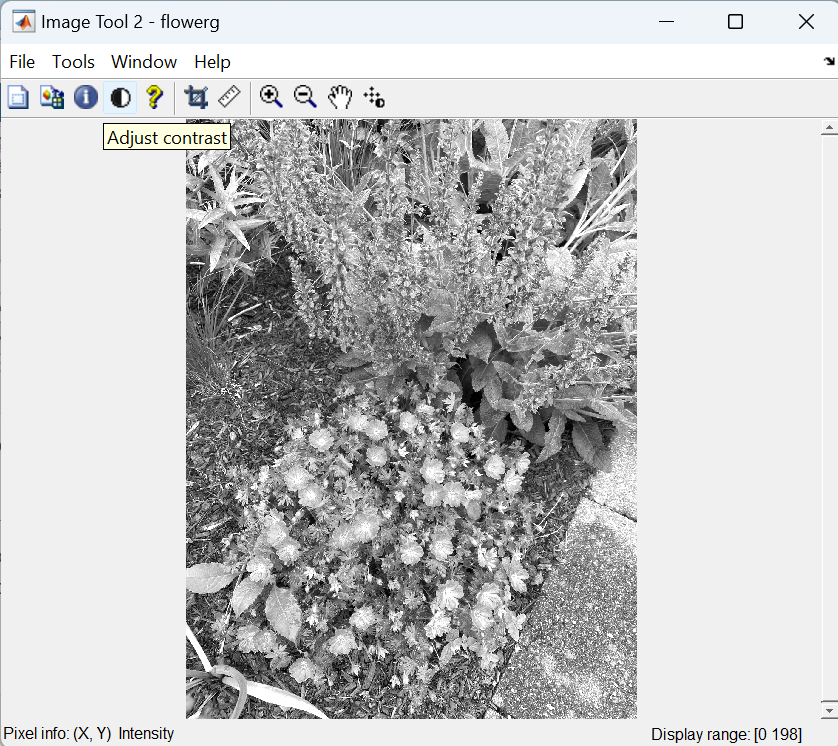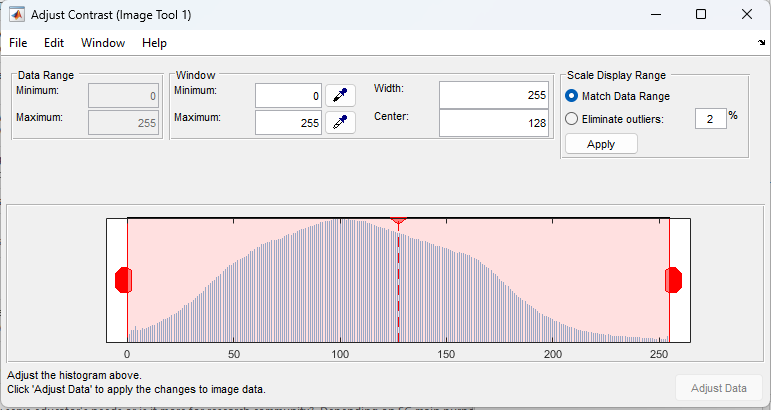

When you're done playing around with the contrast in this window, close both `imtool` windows. 

## 3: Segment image by color

Often, when working with biological images, we want to segment them into different parts. This is sometimes referred to as identifying regions of interest in an image. There are lots of ways to do this: find edges, compare the foreground to the background of the image, look for shapes and sizes of an object, or segment by color. 

Consider our original flower image. If we wanted to segment one group of flowers, how do you think you might do this? 

When I look at this image, the beautiful colors of both the pink and purple flowers stand out to me! Let's try segmenting by color. 

### Color segmentation via the Color Thresholder app

Let's navigate to the **Apps** tab, and select 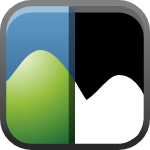 **Color Thresholder**. Select ** Load Image **and** l**oad the original color image `flowers` (from the Workspace is the easiest!). 

You'll be prompted to select a [colorspace](https://en.wikipedia.org/wiki/Color_space). The idea is to rotate each 3-D color space and determine which one separates the colors you are interested in the best (in this case, I want to separate pink from purple, so I'm trying to figure out which colorspace has the most *physical* distance between pink and purple). You can select any colorspace you think will work and see how segmentation in that color space works because you can always go back and try the other spaces. 

If you're curious: RGB is a standard colorspace used in most computer programs, whereas HSV and L*a*b* are designed to more closely approximate human vision. YCbCr is a family of colorspaces that is most often used for digital videography. 

In this case, let's try clicking on **YCbCr**. You'll see the image on the left, and sliders where you can adjust the luminance, blue color difference, and red color difference on the right. Changing these will change the pixels displayed. You can rotate the colorspace, and start adjusting the sliders. As you adjust, you'll remove parts of the image that no longer fall into those Y, Cb, and Cr values. 

  Try to isolate the pink flowers (*hint*: adjust one color difference at a time). 

First, I used the Cb slider (blue difference) to isolate the purple and pink flowers from everything in the background. 

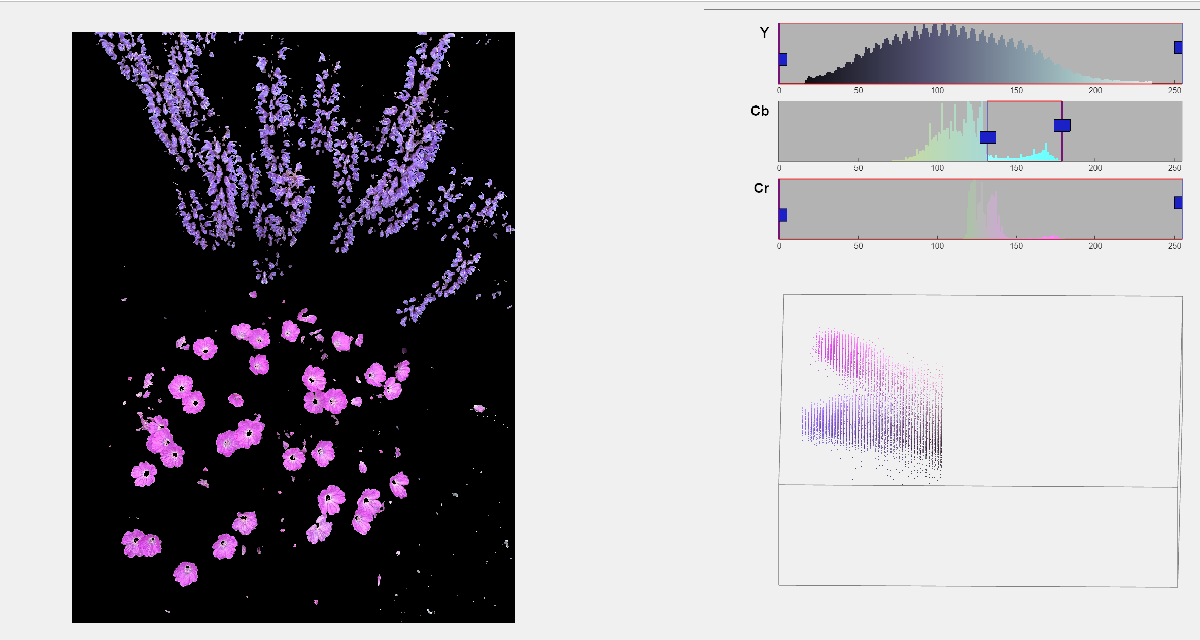

Then, use the red difference slider to isolate pink from purple. 

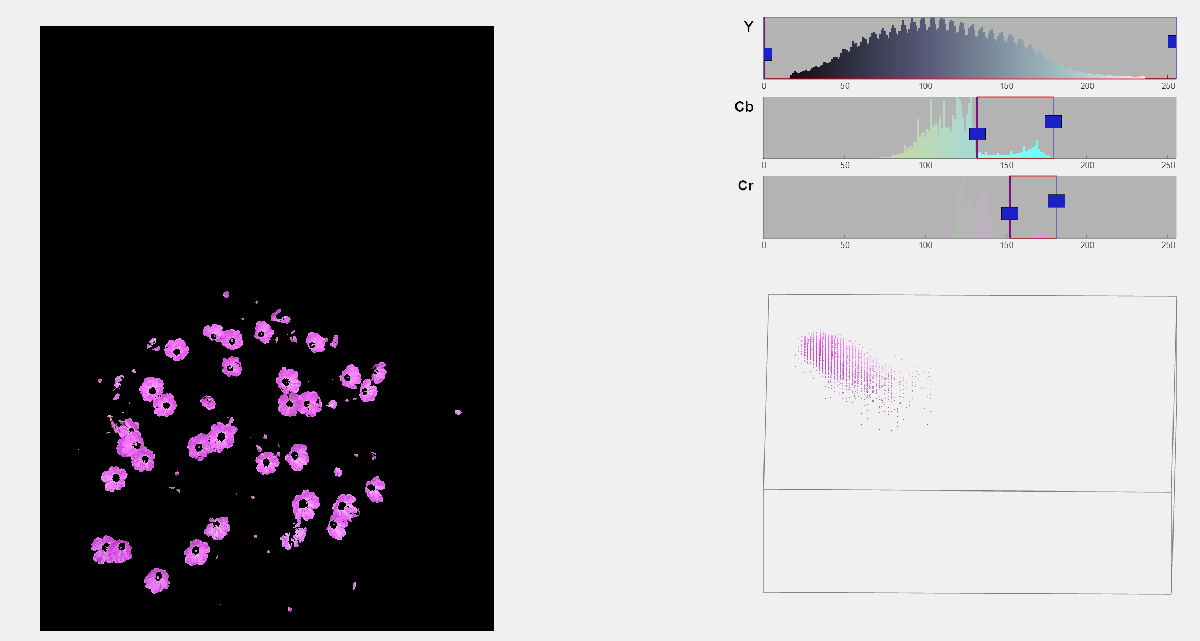

You'll see the color values you've selected in the color space on the bottom right.

Selecting 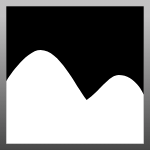**Show Binary** will show you the binary mask that this color segmentation creates. This mask can then be applied to the image in a variety of ways. 

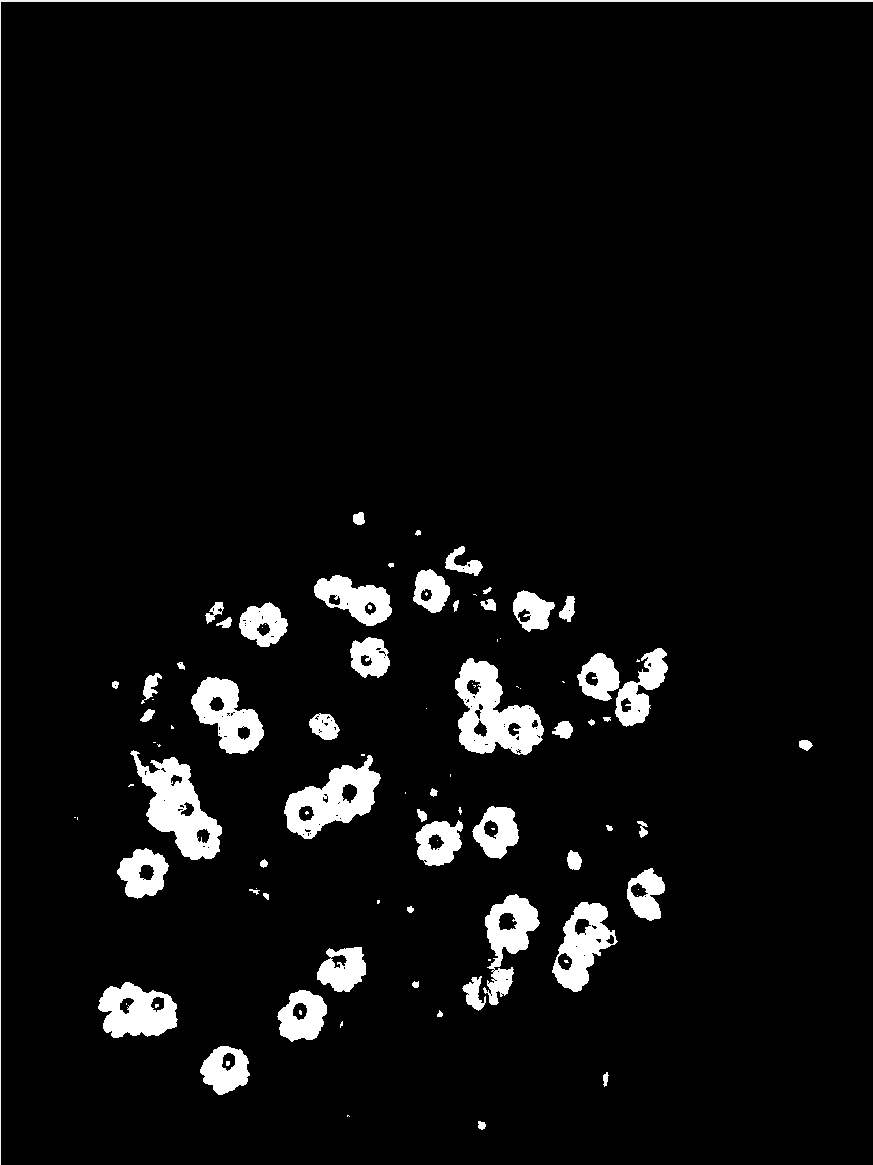  

Export both this image and an array that contains the mask you made here by selecting 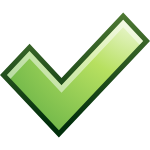**Export **and then** OK: **

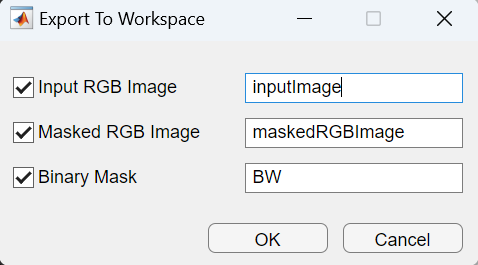

If you want to utilize the mask, it will be saved as a variable named `BW`. Note that you can also export a function to recreate this mask. Once everything is exported to your workspace, you can close the Color Thresholder app. 

Let's apply this mask to our original image. We can overlay this mask on our grayscale version of the image to determine where the pink flowers are by using [`imoverlay()`](https://www.mathworks.com/help/images/ref/imoverlay.html). Run: 

overlaid = imoverlay(flowerg, BW);
figure()
imshow(overlaid)

Nice, our flowers have been highlighted! 

When we exported the mask, we also exported a version of the initial colored image with the mask applied, called `maskedRGBimage`.

  Pull `maskedRGBimage` up using `imshow()`:

You can probably imagine how we might use this for further analysis-- we could, for example, create a program that identifies flower types in an ecosystem by specific colors. 

### Making measurements

Biologists collect a lot of information about the plants they study. One example might be the size of a flower at a given point in a plant's life. Let's clean this image up a bit and then determine the size of this plant's flowers. 

#### A quick measurement of a single flower

Let's open up our masked image using` imtool()`! 

  Type `imtool(maskedRGBImage)`

imageViewer(maskedRGBImage)

You can click the little ruler, which allows you to measure the distance between two pixels. Click on one pixel, then drag across the screen to another pixel to measure the distance (in pixels) between the two points (you may need to zoom in using the magnifying glass in the toolbar). For example, you can find the span of a single flower:

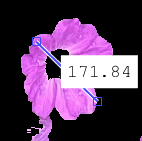

Suppose we had a scalebar on our image that told us that 86 pixels in our image span one centimeter. How would we find the number of centimeters that the flower above spans?

Divide the number of pixels measured by the conversion rate in pixels/cm (pixels/(pixels/cm) gives an answer in cm)! 

flower_span = 171.84/86 

Ok, so our flower spans about 2 cm across.

When you're done making measurements of these flowers, you can close the `imtool` window. 

#### Make measurements of the flower population overall

Let's find a distribution of flower size in our image. Is the measured 2 cm the average size of all flowers? 

First, let's remove the noise, or those pesky little patches of pink that aren't flowers. We can remove small objects from a binary image like this by using [`bwareaopen()`](https://www.mathworks.com/help/images/ref/bwareaopen.html)**. **We need to input to this function the binary image (saved as `BW`) and a value `P`, which is the minimum number of pixels an object should have to not be deleted. 

We're using quite a large value of `P` because if we measure these splotches in `imtool` some of them have quite a large area in pixels, so P needs to be large to remove them. 

BW2 = bwareaopen(BW, 3000);

We can see what that looks like by displaying the mask `BW` and the de-splotched `BW2` side by side. [`imshowpair()`](https://www.mathworks.com/help/images/ref/imshowpair.html) is a built-in function in the Image Processing Toolbox, which allows you to compare two images. Using it with the "`montage" `option opens the images side by side. 

imshowpair(BW,BW2, "montage")

Next, let's open the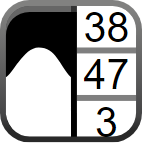 **Image Region Anaylzer **app and open this cleaned-up image, `BW2`. You can do this by navigating to the app, or the single line of code here: 

imageRegionAnalyzer(BW2)

Let's fill the holes in the middle of each flower so that we can look at each flower as a single shape. 

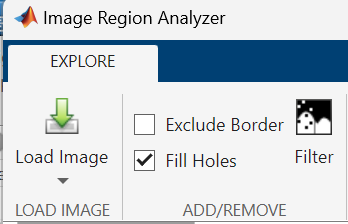

You can simply select "Fill holes". To do this in a line of code, check out the function [`imfill()`](https://www.mathworks.com/help/images/ref/imfill.html).

On the right side of the app, you can see a list of the properties of the regions in the image MATLAB has identified. You can sort the areas from smallest to largest by clicking the arrow next to area, and then you can click on different measurements in the table to see which region in the image these correspond to.

The idea for us will be to filter this mask so we only show regions that contain single flowers, and then we can use that to determine the average size of flowers in our image! 

So for example, the area I'm looking at here is too small to be a whole flower. A good minimum area to use here is probably 8000 pixels. 

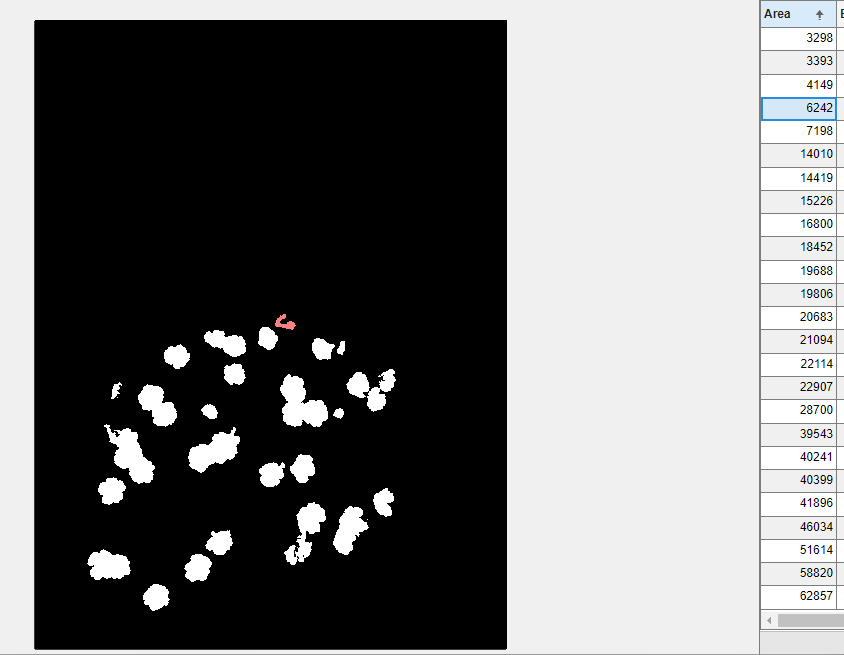

On the other end, some of these large areas are a result of single flowers being grouped together. There are advanced algorithms we can use to separate these, but that's beyond the scope of this module. For now, we have plenty of flowers to measure from, so let's make life a little easier and just delete those. A good maximum area in this example would be anything around 22500. So let's sort from our minimum to maximum area. 

Select 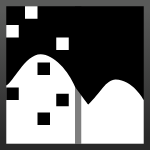 **Filter** at the top of the app pane, and filter by area. 

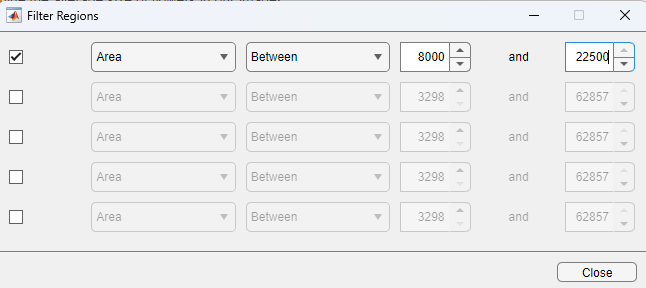

Click the Close button to apply the filter. Then export the properties of each region as a table (`propsTable`). 

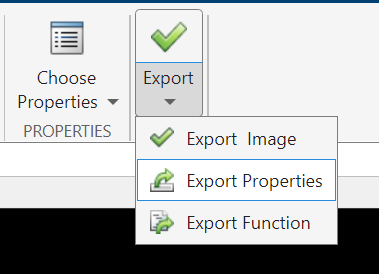

Now let's make a distribution of the radii of the flowers we have left. 

Recall that 1 cm corresponds to 86 pixels in the image. The variable `propsTable` we just exported has a field called `EquivDiameter`, and if we divide this diameter by 86 we will get the diameter of the flower in centimeters: 

diam_cm = propsTable.EquivDiameter/86; 
histogram(diam_cm,6) 
xlabel("Flower span (cm)")
ylabel("Frequency")

We can use some of the descriptive statistics we learned in the biosciences statistics module***(add link to module 2 on File Exchange)*** here as well.  For example, what's the average size of a flower? 

  Calculate the average size of a flower using `mean(diam_cm)`. Save the answer as `avg_flowerspan`: 

  How close is this measured average to the 2 cm span of the one flower we measured? 

We can calculate the percent error of our measurement of 2 cm from the calculated average. Percent error is the difference between the measured and true value, divided by the true value. Multiplying this fraction by 100 gives the percent error. 

my_measurement = 2; 
percent_error = ((my_measurement- avg_flowerspan)/ avg_flowerspan)*100

 What is our percent error here? Note that a 10-20% error is considered normal, so when we fall within that range we can say we did a pretty good job of estimating flower size. 

We've gone through one example of how we might analyze a biological image. In the next section, we will analyze an image of cells on a microscope slide to count how many we see! For more practice and information, check out the [Image Processing Onramp](https://matlabacademy.mathworks.com/details/image-processing-onramp/imageprocessing)! 

[Go to next section (Cell counting)](matlab: edit S3_Cell_counting.mlx)

[Back to introduction](matlab: edit S1_Introduction.mlx)